# Reduced order model for the soft robot

clearvars;
close all
clc

## Import data

See mat file in [https://drive.google.com/drive/u/0/folders/1z2GUDNL4oAfWPNIhuZ-e4d7AcqhTlSBM](https://drive.google.com/drive/u/0/folders/1z2GUDNL4oAfWPNIhuZ-e4d7AcqhTlSBM) 

load dataDecayObs 
nTraj = size(oData,1);
rdof = 3;
odof = 3;
ndof = size(Xsnapshots,1)/2;
Ts = 0.05;

% Process the data
sim_data = {};
sim_data.oData = oData; sim_data.yData = yData;

resampled_data = data.resample(sim_data, Ts);
oData = resampled_data.oData;
yData = resampled_data.yData;

## Plot trajectories in an observable of interest

outdofs = [1 2 3];
customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(oData{iTraj,2}(outdofs(1),:),oData{iTraj,2}(outdofs(2),:),oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end
view(3)
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');


customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:nTraj
    subplot(311);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{iTraj,1},oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end


customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(oData{iTraj,2}(outdofs(1),:),oData{iTraj,2}(outdofs(1)+odof,:),oData{iTraj,2}(outdofs(3),:),'Linewidth',1)
end
view(3)
xlabel('$x$','Interpreter','latex');
ylabel('$\dot{x}$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');

## Show PCA infos

Modes were already computed to get yData

% Perform SVD on displacement field
[~,S,~] = svd(Xsnapshots(1:ndof,:),0);
% Plot variance description: we expect three modes to capture almost all
% variance. Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('RIC [%]');
xlim([1 9])
set(gca,'XTick',[1:1:9])

## Obtain reduced-order coordinates

customFigure; colororder(cool(nTraj));
for iTraj = 1:nTraj
    plot3(yData{iTraj,2}(1,:),yData{iTraj,2}(1+rdof,:),oData{iTraj,2}(2,:),'Linewidth',1)
end
view(3)
xlabel('$u_1$','Interpreter','latex');
ylabel('$\dot{u}_1$','Interpreter','latex');
zlabel('$u_2$','Interpreter','latex');


customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(nTraj));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:nTraj
    subplot(311);
    plot(yData{iTraj,1},yData{iTraj,2}(1,:),'Linewidth',1)
    subplot(312);
    plot(yData{iTraj,1},yData{iTraj,2}(2,:),'Linewidth',1)
    subplot(313);
    plot(yData{iTraj,1},yData{iTraj,2}(3,:),'Linewidth',1)
end

## Train and test data

indTest = [1 3 5 7 9 11 13 15];
indTrain = setdiff(1:nTraj,indTest);

## Truncate trajectories

sliceInt = [0.14 2.6];
oDataTrunc = sliceTrajectories(oData, sliceInt);
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Train Geometery of the SSM

SSMDim = 2*rdof;
SSMOrder = 3;
IMInfo = IMGeometry(oDataTrunc(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',yDataTrunc(indTrain,:));
IMInfoInv = IMGeometry(yDataTrunc(indTrain,:),SSMDim, SSMOrder,'reducedCoordinates',oDataTrunc(indTrain,:));

Evaluate parametrization error

% Compute and display error
% Train error
errorGeoTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTrain(iTraj),:));
    errorGeoTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGeoTrain

errorGeoTrain =     0.2824    0.2398    0.2262    0.3250    0.2017    0.1805    0.2701    0.2470    0.2276    0.3348    0.1795    0.2022    0.2684    0.2863    0.2416    0.2924    0.1241    0.2813    0.1894    0.2454    0.1365    0.1322    0.1977    0.2543    0.2461    0.2132    0.1814    0.2278    0.1540    0.2503    0.2923    0.3472    0.5046    0.3526    0.3939    0.4522    0.2228    0.2231    0.2417    0.3453    0.3257    0.4237    0.3196    0.6342


meanErrorGeoTrain = mean(errorGeoTrain)

meanErrorGeoTrain = 0.2709

%
errorGeoTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    oRec = liftTrajectories(IMInfo, yDataTrunc(indTest(iTraj),:));
    errorGeoTest(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(oRec{1,1},oRec{1,2}(outdofs(1),:),'k:','Linewidth',2)
    subplot(312);
    plot(oRec{1,1},oRec{1,2}(outdofs(2),:),'k:','Linewidth',2)
    subplot(313);
    plot(oRec{1,1},oRec{1,2}(outdofs(3),:),'k:','Linewidth',2)
end

errorGeoTest

errorGeoTest =     0.2273    0.2306    0.2663    0.2699    0.2423    0.1570    0.2006    0.3497


meanErrorGeoTest = mean(errorGeoTest)

meanErrorGeoTest = 0.2430

Evaluate chart error

% Compute and display error
% Train error
errorGeoCTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    yRec = liftTrajectories(IMInfoInv, oDataTrunc(indTrain(iTraj),:));
    errorGeoCTrain(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTrain(iTraj),:))*100;
end
errorGeoCTrain

errorGeoCTrain =     0.1668    0.1632    0.1953    0.2466    0.2012    0.1399    0.2163    0.2052    0.1753    0.2246    0.1193    0.1507    0.1789    0.1750    0.1716    0.2049    0.1373    0.2129    0.1218    0.1464    0.1288    0.1442    0.1816    0.1797    0.1774    0.1987    0.1044    0.1424    0.1256    0.2129    0.1504    0.1886    0.3381    0.3651    0.3533    0.4709    0.1639    0.1729    0.1580    0.1995    0.3033    0.4141    0.2252    0.5955


meanErrorGeoCTrain = mean(errorGeoCTrain)

meanErrorGeoCTrain = 0.2102

%
errorGeoCTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    yRec = liftTrajectories(IMInfoInv, oDataTrunc(indTest(iTraj),:));
    errorGeoCTest(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(yRec{1,1},yRec{1,2}(outdofs(1),:),'k:','Linewidth',2)
    subplot(312);
    plot(yRec{1,1},yRec{1,2}(outdofs(2),:),'k:','Linewidth',2)
    subplot(313);
    plot(yRec{1,1},yRec{1,2}(outdofs(3),:),'k:','Linewidth',2)
end

errorGeoCTest

errorGeoCTest =     0.1252    0.1457    0.2150    0.1865    0.1854    0.1267    0.1918    0.2750


meanErrorGeoCTest = mean(errorGeoCTest)

meanErrorGeoCTest = 0.1814

Store map in the same variables

sVar = {'map', 'polynomialOrder', 'dimension', 'nonlinearCoefficients', 'phi', 'exponents'};
for iVar = 1:length(sVar)
    IMInfo.chart.(sVar{iVar}) = IMInfoInv.parametrization.(sVar{iVar});
end

## Train Dynamics of the SSM (mechanical style - discrete dynamical system)

ROMOrder = 3;
RDInfo = IMDynamicsMap(yDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -3.4506 +16.8012i
  -3.5473 +17.0688i
  -3.5260 +18.3882i




yRec = advectRD(RDInfo, yDataTrunc);

normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 0.9645

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 0.6481


plotAll = 0;
if plotAll == 1
    vPlot = 1:nTraj;
else
    vPlot = indTest;
end
customFigure('subPlot',[3 1]);
xlabel('$t$','Interpreter','latex');
ylabel('$u_1$','Interpreter','latex');
subplot(312); 
xlabel('$t$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');
subplot(313); colororder(cool(length(vPlot)));
xlabel('$t$','Interpreter','latex');
ylabel('$u_3$','Interpreter','latex');
for iTraj = vPlot
    subplot(311);
    plot(yData{iTraj,1},yData{iTraj,2}(1,:),'Linewidth',1)
    subplot(312);
    plot(yData{iTraj,1},yData{iTraj,2}(2,:),'Linewidth',1)
    subplot(313);
    plot(yData{iTraj,1},yData{iTraj,2}(3,:),'Linewidth',1)
end
for iTraj = vPlot
    subplot(311);
    plot(yRec{iTraj,1},yRec{iTraj,2}(1,:),'k:','Linewidth',1)
    subplot(312);
    plot(yRec{iTraj,1},yRec{iTraj,2}(2,:),'k:','Linewidth',1)
    subplot(313);
    plot(yRec{iTraj,1},yRec{iTraj,2}(3,:),'k:','Linewidth',1)
end

## Evaluate global error

% Train error
errorGloTrain = zeros(1,length(indTrain));
for iTraj = 1:length(indTrain)
    oRec = liftTrajectories(IMInfo, yRec(indTrain(iTraj),:));
    errorGloTrain(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTrain(iTraj),:))*100;
end
errorGloTrain

errorGloTrain =     0.4749    0.5071    1.0334    0.8850    1.0852    1.2442    1.0088    1.0681    0.5459    0.8000    0.6716    0.5055    0.8789    0.9701    0.5399    1.1337    0.4629    0.8957    1.0033    0.7757    0.5087    0.7416    0.3534    0.8066    0.5922    0.3083    0.5555    0.6569    0.5391    0.8467    0.9921    1.3872    2.7243    1.1127    3.6581    1.8799    1.1642    1.0934    0.6664    0.8734    2.7502    0.9262    1.3552    2.5109


meanErrorGloTrain = mean(errorGloTrain)

meanErrorGloTrain = 1.0339

%
errorGeoTest = zeros(1,length(indTest)); 
customFigure('subPlot',[3 1]); 
subplot(311); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313); colororder(cool(length(indTest)));
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
for iTraj = 1:length(indTest)
    subplot(311);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(1),:),'Linewidth',1)
    subplot(312);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(2),:),'Linewidth',1)
    subplot(313);
    plot(oData{indTest(iTraj),1},oData{indTest(iTraj),2}(outdofs(3),:),'Linewidth',1)
end
for iTraj = 1:length(indTest)
    oRec = liftTrajectories(IMInfo, yRec(indTest(iTraj),:));
    errorGloTest(iTraj) = computeTrajectoryErrors(oRec, oDataTrunc(indTest(iTraj),:))*100;
        subplot(311);
    plot(oRec{1,1},oRec{1,2}(outdofs(1),:),'k:','Linewidth',1)
    subplot(312);
    plot(oRec{1,1},oRec{1,2}(outdofs(2),:),'k:','Linewidth',1)
    subplot(313);
    plot(oRec{1,1},oRec{1,2}(outdofs(3),:),'k:','Linewidth',1)
end

errorGloTest

errorGloTest =     0.6108    0.7806    1.1066    1.0275    1.1415    0.4588    0.5589    0.6605


meanErrorGloTest = mean(errorGloTest)

meanErrorGloTest = 0.7932

## Understand which mode is more responsbile for what motion

outdofsMat = zeros(3,2*ndof);
output_node = 1354;
outdofsPS =  3*output_node + [1 2 3];

for ii = 1:3
outdofsMat(ii,outdofsPS(ii)) = 1;
end

redDynLinearPart = RDInfo.reducedDynamics.coefficients(:,1:2*rdof);
redStiffnessMat = -redDynLinearPart(rdof+1:end,1:rdof);
[UconsRedDyn,w2] = eig(redStiffnessMat);
[consFreqs,pos] = sort(sqrt(diag(w2))); UconsRedDyn = UconsRedDyn(:,pos);
[consFreqs abs(RDInfo.eigenvaluesLinPartFlow(1:3))];
Ucons = [UconsRedDyn zeros(rdof); zeros(rdof) UconsRedDyn];
Vcons = V*Ucons;
abs(RDInfo.eigenvaluesLinPartFlow(1:3))

ans =    17.1519
   17.4335
   18.7232


modesDir = outdofsMat*Vcons(:,1:rdof)

modesDir =     0.0396   -0.0000   -0.0170
    0.0139   -0.0449   -0.0061
    0.0185    0.0002    0.0451


% Plots mode direction
customFigure; classicColors = colororder;
for ii = 1:3
plot3([0 modesDir(1,ii)],[0 modesDir(2,ii)],[0 modesDir(3,ii)],'Linewidth',1,'Color',classicColors(ii,:))
plot3([modesDir(1,ii)],[modesDir(2,ii)],[modesDir(3,ii)],'.','MarkerSize',12,'Color',classicColors(ii,:),'HandleVisibility','off')
end
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
legend(['Mode 1 - $\omega =  ' num2str(abs(RDInfo.eigenvaluesLinPartFlow(1))) '$'],...
    ['Mode 2 - $\omega =  ' num2str(abs(RDInfo.eigenvaluesLinPartFlow(2))) '$'],...
    ['Mode 3 - $\omega =  ' num2str(abs(RDInfo.eigenvaluesLinPartFlow(3))) '$'],'interpreter','latex')
view(3)
axis equal

% Hence mode 1 is mainly along x, mode 2 along y and mode 3 along z.

## Control


$$H_{\textrm{red}} ={\mathrm{V}}^{\top } M^{-1} H$$


Hred = transpose(V(1:ndof,1:rdof))*(M\H);

normsModalForcing = mean((transpose(V(1:ndof,1:rdof))*(M\H)).^2,1)

normsModalForcing = 	1.0e+03 *

    3.6165    3.6851    2.7069    3.6295


normsNonModalForcing = mean(((eye(ndof)-V(1:ndof,1:rdof)*transpose(V(1:ndof,1:rdof)))*(M\H)).^2,1)

normsNonModalForcing = 	1.0e+03 *

    1.8746    1.5411    1.3337    1.2016


## Setup model for control

Accordin to the slides of June 2

dt_actual = 0.05;
Rauton = RDInfo.reducedDynamics.map;
R = @(k,p,u) Rauton(p) + dt_actual * [zeros(rdof,size(Hred,2)); Hred]*u;
C = IMInfo.parametrization.map;
W = IMInfo.chart.map;

% Example
DeltaT = yData{1,1}(2)-yData{1,1}(1);
uFun = @(k) [atan(DeltaT*k)/pi*2; 0; 0; 0];
iters = 0:15000;
yTraj = iterateMapU(@(k,p) R(k,p,uFun(k)),length(iters),zeros(2*rdof,1));
oTraj = C(yTraj);
customFigure('subPlot',[3 1]); 
subplot(311); 
xlabel('$t$','Interpreter','latex');
ylabel('$x$','Interpreter','latex');
subplot(312); 
xlabel('$t$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
subplot(313);
xlabel('$t$','Interpreter','latex');
ylabel('$z$','Interpreter','latex');
subplot(311);
plot(iters*DeltaT,oTraj(outdofs(1),:),'Linewidth',1)
xlim([iters(1) iters(end)]*DeltaT)
subplot(312);
plot(iters*DeltaT,oTraj(outdofs(2),:),'Linewidth',1)
xlim([iters(1) iters(end)]*DeltaT)
subplot(313);
plot(iters*DeltaT,oTraj(outdofs(3),:),'Linewidth',1)
xlim([iters(1) iters(end)]*DeltaT)

## Integrate the model with inputs

% Load the controls and actual trajectories for figure eight
uFigureEight = readmatrix("../system_data/u_big.csv");
z = readmatrix("../system_data/z_big.csv").';
z_eq = readmatrix("../system_data/z_equilibrium.csv").';
z_eq = [z_eq, 0, 0, 0];

% Original spacing of inputs
T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1)

t_span =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


t_interp = linspace(1,T,T/DeltaT);
z_ref = repmat(z_eq.', 1, length(t_interp)+1)

z_ref =    -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769   -7.0769
    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132    1.2132 

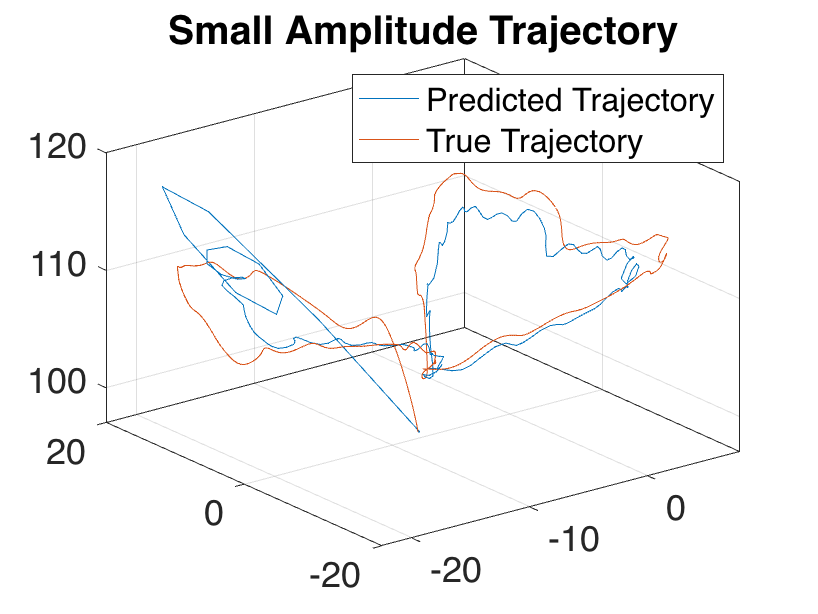

z_true = z(4:end, :);

% TODO: Looks like this may be wrong when compared to scipy....
u_interp = interp1(t_span, uFigureEight, t_interp);

uFun = @(k) u_interp(k,:).';
iters = 0:length(t_interp);
yTraj = iterateMapU(@(k,p) R(k,p,uFun(k)),length(iters),zeros(2*rdof,1));
oTraj = C(yTraj) + z_ref;

% Visualize the trajectory
customFigure; 
plot3(oTraj(1, :), oTraj(2, :), oTraj(3, :)); 
plot3(z_true(1, :), z_true(2, :), z_true(3, :)); 
legend('Predicted Trajectory', 'True Trajectory')
title('Small Amplitude Trajectory')
view(3)

## Reduced dynamics infos

The reduced dynamics is a map of type:

RDInfo.reducedDynamics.map

where the coefficients $W_r$ are

RDInfo.reducedDynamics.coefficients

and the function $\phi$ collects all the monomials for the states up to the fitting order

RDInfo.reducedDynamics.phi

the coefficients of these monomials are stored in the matrix

RDInfo.reducedDynamics.exponents